# 2.3 標本を視えるようにする

### 図 2.3.1 平均値の棒グラフの危険性

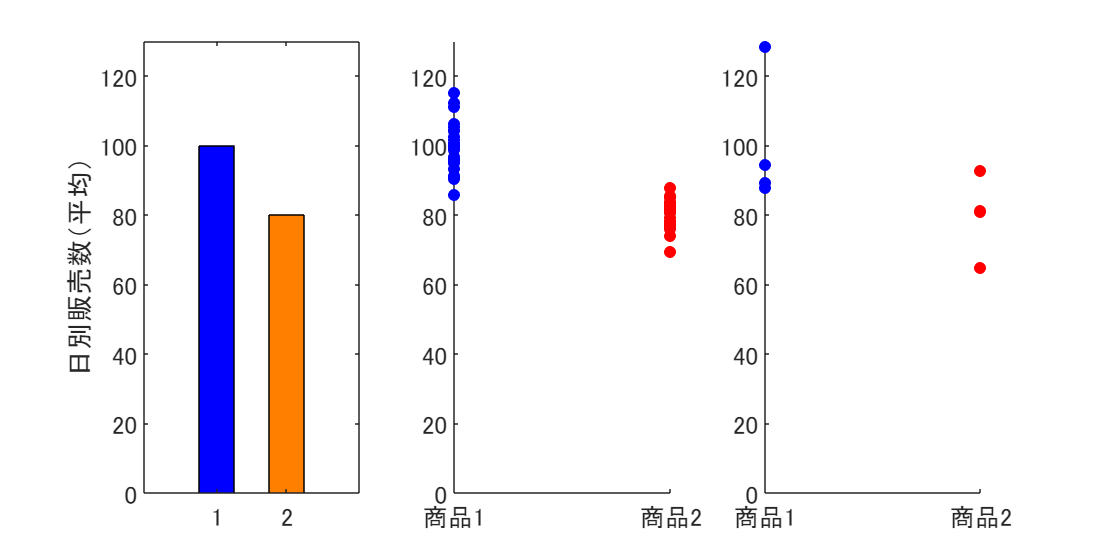

% Set font size
set(0, 'DefaultAxesFontSize', 14);

% Data generation
rng(0); % Set random seed for reproducibility

% Product 1 daily sales
product1_small_var = normrnd(100, 5, [30, 1]); % Generate 30 normally distributed random numbers with mean 100 and std 5
product1_small_var = product1_small_var - mean(product1_small_var) + 100; % Adjust mean to 100

product1_large_var = normrnd(100, 20, [4, 1]); % Generate 4 normally distributed random numbers with mean 100 and std 20
product1_large_var = product1_large_var - mean(product1_large_var) + 100; % Adjust mean to 100

rng(2); % Set random seed for reproducibility
% Product 2 daily sales
product2_small_var = normrnd(80, 5, [30, 1]); % Generate 30 normally distributed random numbers with mean 80 and std 5
product2_small_var = product2_small_var - mean(product2_small_var) + 80; % Adjust mean to 80

product2_large_var = normrnd(80, 20, [4, 1]); % Generate 4 normally distributed random numbers with mean 80 and std 20
product2_large_var = product2_large_var - mean(product2_large_var) + 80; % Adjust mean to 80

% Create data tables
data_small_var_product1 = table(repmat({'商品1'}, 30, 1), product1_small_var, 'VariableNames', {'商品', '日別販売数'});
data_small_var_product2 = table(repmat({'商品2'}, 30, 1), product2_small_var, 'VariableNames', {'商品', '日別販売数'});
data_large_var_product1 = table(repmat({'商品1'}, 4, 1), product1_large_var, 'VariableNames', {'商品', '日別販売数'});
data_large_var_product2 = table(repmat({'商品2'}, 4, 1), product2_large_var, 'VariableNames', {'商品', '日別販売数'});

% Concatenate data tables
data_small_var = [data_small_var_product1; data_small_var_product2];
data_large_var = [data_large_var_product1; data_large_var_product2];

% Create figure
figure('Position', [100, 100, 1000, 500]);

% Bar plot
subplot(1, 3, 1);
bar([1, 2], [100, 80], 0.5, 'FaceColor', 'flat', 'CData', [0 0 1; 1 0.5 0]);
ylim([0, 130]);
ylabel('日別販売数（平均）');

% Strip plot (small variance)
subplot(1, 3, 2);
hold on;
scatter(ones(size(product1_small_var)), product1_small_var, 'filled', 'MarkerFaceColor', 'blue');
% scatter(2*ones(size(product2_small_var)), product2_small_var, 'filled', 'MarkerFaceColor', 'orange');
scatter(2*ones(size(product2_small_var)), product2_small_var, 'filled', 'MarkerFaceColor', 'red');
ylim([0, 130]);
set(gca, 'xtick', [1, 2], 'xticklabel', {'商品1', '商品2'});
hold off;

% Strip plot (large variance)
subplot(1, 3, 3);
hold on;
scatter(ones(size(product1_large_var)), product1_large_var, 'filled', 'MarkerFaceColor', 'blue');
% scatter(2*ones(size(product2_large_var)), product2_large_var, 'filled', 'MarkerFaceColor', 'orange');
scatter(2*ones(size(product2_large_var)), product2_large_var, 'filled', 'MarkerFaceColor', 'red');
ylim([0, 130]);
set(gca, 'xtick', [1, 2], 'xticklabel', {'商品1', '商品2'});
hold off;

% Save the figure as an image
saveas(gcf, '2_3_1_group_comparison.png');

### 図 2.3.2 様々な標本の可視化

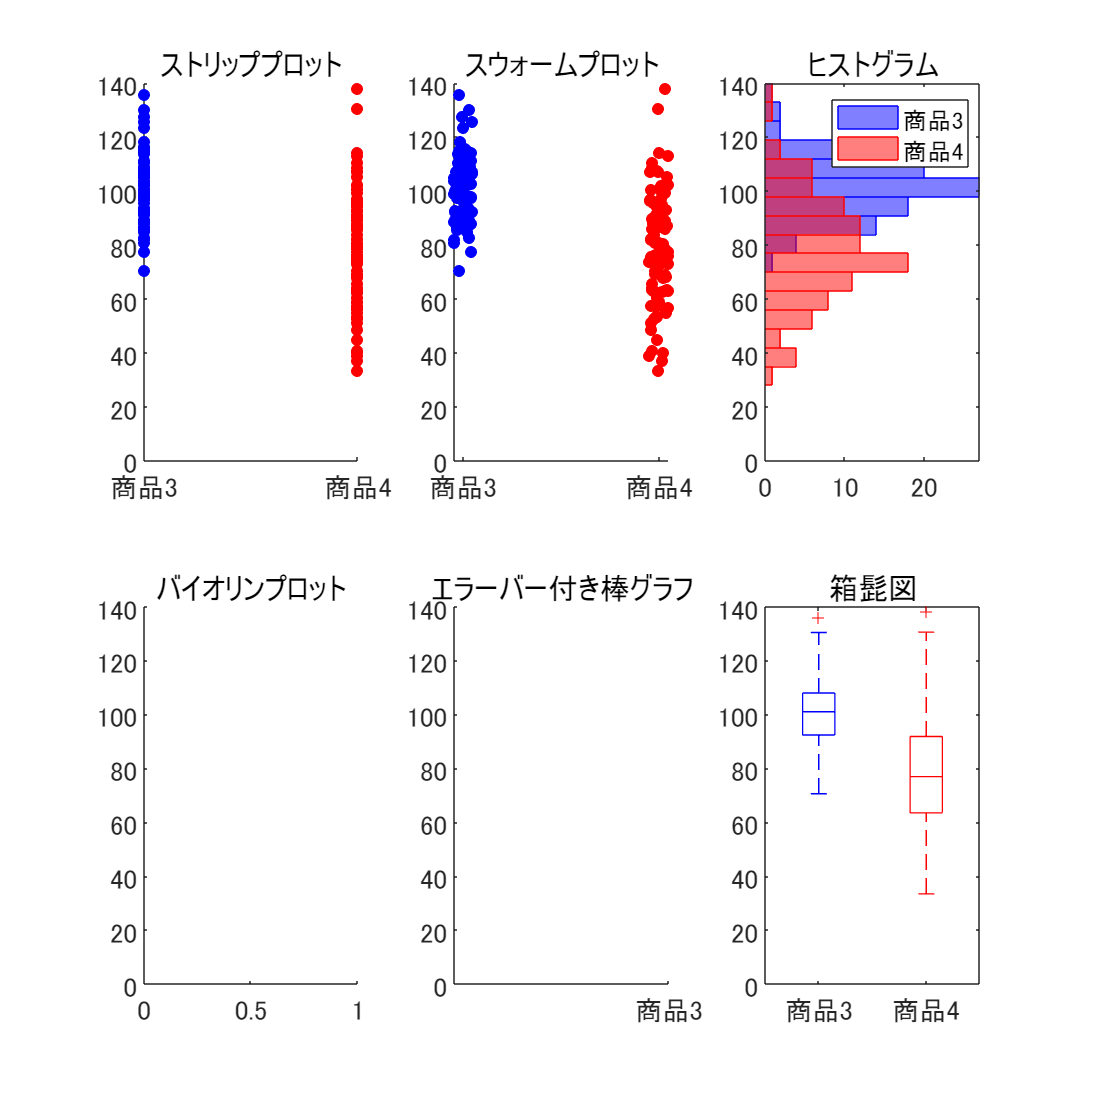

% Set font size
set(0, 'DefaultAxesFontSize', 15);

% Data generation
rng(0); % Set random seed for reproducibility
num_samples = 100; % Sample size
% Generate num_samples random numbers from a normal distribution with mean 100 and std 10
category1 = normrnd(100, 10, [num_samples, 1]);
% Generate num_samples random numbers from a normal distribution with mean 80 and std 20
category2 = normrnd(80, 20, [num_samples, 1]);

% Create data table
categories = [repmat({'商品3'}, num_samples, 1); repmat({'商品4'}, num_samples, 1)];
values = [category1; category2];
data = table(categories, values, 'VariableNames', {'Category', 'Value'});

% Create subplots
fig = figure('Position', [100, 100, 1000, 1000]);

% Strip plot (using scatter plot as MATLAB does not have a direct equivalent)
subplot(2, 3, 1);
hold on;
scatter(ones(size(category1)), category1, 'filled', 'MarkerFaceColor', 'b');
scatter(2*ones(size(category2)), category2, 'filled', 'MarkerFaceColor', 'r');
hold off;
title('ストリッププロット');
ylim([0, 140]);
set(gca, 'xtick', [1, 2], 'xticklabel', {'商品3', '商品4'});

% Swarm plot (using scatter plot with jittering as MATLAB does not have a direct equivalent)
subplot(2, 3, 2);
hold on;
scatter(ones(size(category1)) + 0.1*(rand(size(category1))-0.5), category1, 'filled', 'MarkerFaceColor', 'b');
scatter(2*ones(size(category2)) + 0.1*(rand(size(category2))-0.5), category2, 'filled', 'MarkerFaceColor', 'r');
hold off;
title('スウォームプロット');
ylim([0, 140]);
set(gca, 'xtick', [1, 2], 'xticklabel', {'商品3', '商品4'});

% Histogram
subplot(2, 3, 3);
histogram(category1, 'BinEdges', 0:7:140, 'Orientation', 'horizontal', 'FaceColor', 'b', 'EdgeColor', 'b', 'FaceAlpha', 0.5);
hold on;
histogram(category2, 'BinEdges', 0:7:140, 'Orientation', 'horizontal', 'FaceColor', 'r', 'EdgeColor', 'r', 'FaceAlpha', 0.5);
hold off;
title('ヒストグラム');
ylim([0, 140]);
legend({'商品3', '商品4'});

% Violin plot (using distributionPlot function from File Exchange, if available)
subplot(2, 3, 4);
% distributionPlot({category1, category2}, 'color', {'b', 'r'}, 'showMM', 0);
title('バイオリンプロット');
ylim([0, 140]);

% Bar plot with error bars
subplot(2, 3, 5);
% barwitherr([std(category1), std(category2)], [1, 2], [mean(category1), mean(category2)], 'FaceColor', 'flat', 'CData', [0 0 1; 1 0 0]);
title('エラーバー付き棒グラフ');
ylim([0, 140]);
set(gca, 'xtick', [1, 2], 'xticklabel', {'商品3', '商品4'});

% Box plot
subplot(2, 3, 6);
boxplot(values, categories, 'Colors', ['b', 'r']);
title('箱髭図');
ylim([0, 140]);
set(gca, 'xtick', [1, 2], 'xticklabel', {'商品3', '商品4'});


% Adjust layout
% MATLAB automatically adjusts the layout, so there is no need for an equivalent to plt.tight_layout()

% Save the figure as an image
% saveas(fig, '2_3_2_dist_charts.png');

### 図 2.3.3 箱ひげ図の構成要素

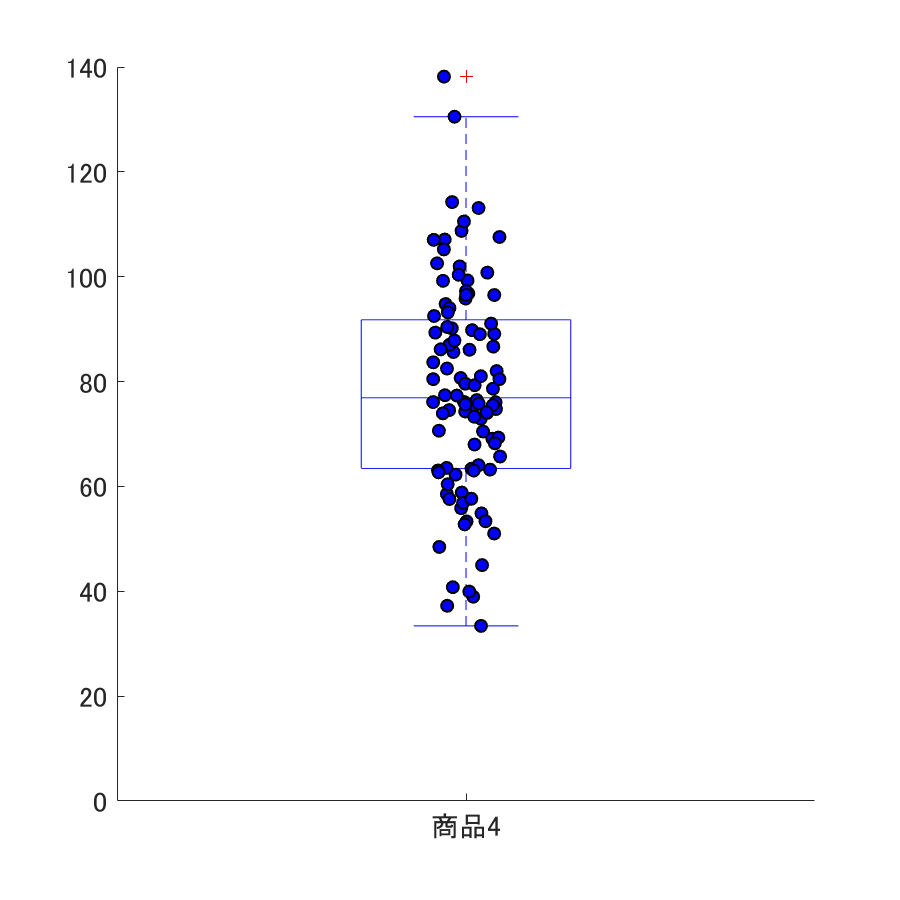

% Set font size
set(0, 'DefaultAxesFontSize', 14);

% Data generation
rng(0); % Set random seed for reproducibility
num_samples = 100; % Sample size
% Generate num_samples random numbers from a normal distribution with mean 100 and std 10
category1 = normrnd(100, 10, [num_samples, 1]);
% Generate num_samples random numbers from a normal distribution with mean 80 and std 20
category2 = normrnd(80, 20, [num_samples, 1]);

% Create data table
categories = [repmat({'商品3'}, num_samples, 1); repmat({'商品4'}, num_samples, 1)];
values = [category1; category2];
data = table(categories, values, 'VariableNames', {'Category', 'Value'});

% Filter data for '商品4' category
data = data(strcmp(data.Category, '商品4'), :);

% Create subplot
fig = figure('Position', [100, 100, 600, 600]);

% Box plot
boxplot(data.Value, data.Category, 'Colors', 'b', 'Widths', 0.3);
hold on;

% Swarm plot (simulated using scatter plot with jittering)
category_values = data.Value;
category_indices = ones(size(category_values));
jittering = 0.1 * (rand(size(category_indices)) - 0.5);
scatter(category_indices + jittering, category_values, 'filled', ...
    'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'b', 'LineWidth', 1);

% Adjust y-axis limits
ylim([0, 140]);

% Remove x and y labels
xlabel('');
ylabel('');

% Remove top and right axis lines
set(gca,'box','off');

% Save the figure as an image
% saveas(fig, '2_3_3_boxplot.png');

% Show the figure
fig.Visible = 'on';